# **02** **Geneze signálů, diskrétní Fourierova transformace (DFT)**

## Geneze signálů

Za signál v dnešním cvičení budeme považovat jednorozměrnou časovou sérii měnící se v čase. Všechny generované signály začínají a končí, jedná se tedy o deterministické signály, finitní. Ačkoliv pro jednoduchost budeme ze začátku využívat harmonických periodických funkcí (sinus), během semestru začneme pracovat i s biologickými signály, tedy signály náhodnými neperiodickými.

Dodržování **vzorkovacího teorému** při vzorkování, časové diskretizaci, je klíčové pro jakékoliv operace se signály. Pokud tuto podmínku nesplníme, původní informaci v signálu nelze korektně interpretovat.

$f_s >2f_{\max }$,

kde $f_s$ je vzorkovací kmitočet a $f_{\max }$ je nejvyšší (nejrychlejší) frekvenční složka signálu.

Signály poté lze zobrazovat ve vzorcích $y\left\lbrack n\right\rbrack$, kde $n\in 0,1,2,\ldotp \ldotp \ldotp ,\left(N-1\right)$ a $N$ je počet vzorků signálu, nebo v diskrétním čase $y\left\lbrack t_n \right\rbrack$. Přepočet mezi vzorky na diskrétní čas se provádí intuitivně přes vzorkovací kmitočet $f_s$, neboli počet vzorků *k* za sekundu. Z trojčlenkou snadno odvodíme vzájemný přepočet:


$$\begin{array}{l}
f_s \;\;\textrm{vzorků}\;\;\ldotp \ldotp \ldotp \;1\;s\\
n\;\textrm{vzorků}\;\;\ldotp \ldotp \ldotp \;t_n 
\end{array}$$



$$t_n =\frac{n}{f_s }$$
 

Obdobně spočítáme i celkovou délku signálu:


$$T=\frac{N}{f_s }$$


Povšimněte si, že pro jednoduchost je první vzorek signálu často značen jako $n=0$ a poslední jako $N-1$. MATLAB ale indexuje od jedničky, tedy $\acute{n} \in 1,2,\ldotp \ldotp \ldotp ,N$, proto výpočet času $t_n$ musí být o jeden vzorek posunut zpět

   
$$t_n =\frac{\acute{n} -1}{f_s }$$


**Pozn.:** Vzorkovací teorém a přepočet vzorků na čas si **dobře zapamatujte**.

## Diskrétní Fourierovy řady

Diskrétní Fourierovy řady  (DFS) je lineární transformací, která rozkládá diskrétní periodický signál $x\left\lbrack t_n \right\rbrack$ (časovou řadu vzorků $n$ odpovídající diskrétnímu času $t_n =\frac{n}{f_s }$, délky/periodou $N_0$ s vzorkovacím kmitočtem $f_s =\frac{1}{T_s }$) na harmonické složky $X\left\lbrack f_k \right\rbrack$ pomocí ortogonální funkce komplexní exponenciály $e^{-i\Omega_k n}$, kde $\Omega_k =2\pi \frac{f_k }{f_s }=2\pi \frac{k}{N_0 }$. Celou operaci si můžeme představit jako výpočet vzájemné energie signálu a komplexní harmonické funkce s frekvencí celého násobku $f_k =\frac{{k\;f}_s }{N_0 }$. Modul komplexního čísla $\left|X\left\lbrack f_k \right\rbrack \right|$ pak reprezentuje amplitudu harmonické složky, která je i rovna vzájemné energii signálu a ortogonální báze s jednotkovou energií. Argument  $\varphi =\arg \left(X\left\lbrack f_k \right\rbrack \right)$ je fáze harmonické složky.

**Komplexní spektrum** reálného signálu je diskrétní, symetrické kolem 0 na intervalu $\left(-\frac{f_s }{2};\;\frac{f_s }{2}\right)$a periodicky se opakující s celým násobkem $f_s$*. *Proto pro výpočet spektra postačí pouze koeficienty s celým násobkem $k\in \left\langle 0,N_0 -1\right\rangle$. Stejnosměrné složce odpovídá $k=0$, tj. $\Omega_k =0,\textrm{tj}\ldotp X\left\lbrack 0\right\rbrack =\frac{1}{N_0 }\sum_{n=0}^{N_0 -1} x\left\lbrack n\right\rbrack e^0$, tj. aritmetický průměr vzorků $X\left\lbrack 0\right\rbrack =\frac{1}{N_0 }\sum_n x\left\lbrack n\right\rbrack$.


$$\begin{array}{l}
\textrm{DFS}:X\left\lbrack f_k \right\rbrack =\frac{1}{N_0 }\sum_{n=0}^{N_0 -1} x\left\lbrack n\right\rbrack e^{-i\Omega_k n} \\
\textrm{IDFS}:x\left\lbrack t_n \right\rbrack =\sum_{k=0}^{N_0 -1} X\left\lbrack f_k \right\rbrack e^{i\Omega_k n} 
\end{array}$$


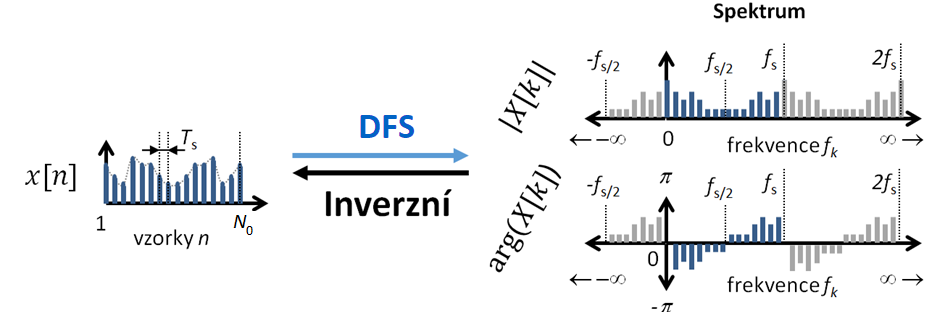

Původní signál $x\left\lbrack t_n \right\rbrack$ můžeme opět získat inverzní transformací (IDFS) prostým součtem všech harmonických komponent $x_k \left\lbrack t_n \right\rbrack$ s odpovídajícími amplitudami a fázovým zpožděním.


$$x_k \left\lbrack t_n \right\rbrack =X\left\lbrack f_k \right\rbrack e^{i\Omega_k n}$$


**Rychlá Fourierova transformace (FFT)**

Výpočetní náročnost DFS je ve složitosti $N^2$. Celé řešení však lze nahradit rekurzí a postupným rozdělováním signálu na části o dvou vzorcích dle známého Cooley-Tukey algoritmu. Celková výpočetní složitost se tak redukuje na $N\;\log \left(N\right)$. Pro optimální výpočet by tedy délka analyzovaného signálu měla mít délku druhé mocniny $N=2^b$*.* Implementace je v MATLAB provedena pomocí funkce `fft()`a pro inverzní transformaci `ifft(). `Ta však oproti DFS vychází z předpisu diskrétní Fourierovy transformace (DFT) pro neperiodické signály délky *N*, tedy normování "periodou" $1/N$ nemůže být na straně dopředné transformace, ale je na straně inverzní. Detailně bude DFT probírána v příštím týdnu.


$$\begin{array}{l}
\textrm{FFT}:X\left\lbrack f_k \right\rbrack =\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack e^{-i\Omega_k n} \\
\textrm{IFFT}:x\left\lbrack t_n \right\rbrack =\frac{1}{N}\sum_{k=0}^{N-1} X\left\lbrack f_k \right\rbrack e^{i\Omega_k n} 
\end{array}$$


Pokud má tedy výpočet pomocí `fft()` odpovídat DFS, tj. modul spektra odpovídat amplitudě frekvenčních komponent, musí být komplexní spektrum v kódu dodatečně normováno $\frac{1}{N}$ a při inverzní transformaci vynásobeno $N$:

To ovšem mírně komplikuje korektní vyjádření magnitudy spektra ${\left|X\left(f_k \right)\right|}_{\textrm{dB}}$ v dB, což by při prostém logaritmování vektoru $X\left\lbrack f_k \right\rbrack$ neodpovídalo definici v** Parsevalově rovnosti** energií v časové a frekvenční oblasti: $\sum_{n=1}^N {\left|x\left\lbrack n\right\rbrack \right|}^2 =\frac{1}{N}\sum_{k=0}^{K-1} {\left|X\left\lbrack f_k \right\rbrack \right|}^2 \ldotp$ 

$20\cdot \log_{10} \left(\frac{1}{N}\left|X\;\left\lbrack f_k \right\rbrack \right|\right)=$$10\cdot \log_{10} \left(\frac{1}{N^2 }{\left|X\;\left\lbrack f_k \right\rbrack \right|}^2 \right)$ ... nikoli požadovaná $10\cdot \log_{10} \left(\frac{1}{N}{\left|X\;\left\lbrack f_k \right\rbrack \right|}^2 \right)$

Při běžné analýze normalizaci $N$ vzorky často úplně ignorujeme, protože hledáme např. nejvyšší spektrální čáry a vynechání normalizace mění pouze měřítko magnitudy, v dB pouze stejnosměrný posun všech čar. Energie signálu počítáme pouze z jedné veličiny intenzity (typicky $U$ nebo $I$) bez známé resistance za předpokladu ($R=1\Omega$), tedy nelze mluvit doslova o energii ve smyslu fyzikálním, hovoříme pak o **výkonovém spktru **či **výkonové spektrální hustotě**. Pro formální úplnost nebo měření energie se všemi známými veličinami je ovšem Parsevalovu rovnost nutno dodržet a umocnění spektra na energetické/výkonové spektrum provézt ještě **před normalizací**.

Pro vykreslování grafů musíme definovat časovou osu signálu v sekundách a frekvenční osu pro spektrum. Uvědomte si, že spektrum DFT má stejný počet spektrálních čar, jako je počet vzorků v signálu $K=N$:

**Inverzní rychlá Fourierova transformace (IFFT) a filtrace ve spektru**

Při IFFT dochází k rekonstrukci signálu součtem harmonických signálů o frekvenci $f_k$, amplitudě $|X\left\lbrack f_k \right\rbrack |$ a fázovém posunu $\varphi \left\lbrack f_k \right\rbrack$. V případě, že chceme ze signálu některé frekvenční složky odstranit - **filtrovat**, můžeme tak učinit ve spektru. Ve spektru nalezneme odpovídající spektrální čáry a vynulujeme je $|X\left\lbrack f_k \right\rbrack |=0;\;\textrm{pro}\;f_k \in \textrm{filtrace}$.

Pozn.: Ačkoli MATLAB pracuje s 64bit přesností (double), i zde dochází k numerickým nepřesnostem, které způsobí po IFFT vznik komplexního signálu (s minimální imaginární složkou) namísto původního čistě reálného. Je tedy nutné používat pouze reálnou složku výsledku.

**Cíle úlohy**

**Geneze signálů**

   ** 1) Vygenerujte si harmonický signál**

- 
$$y\left\lbrack t_k \right\rbrack =Y_0 +Y_{\max } \sin \left(2\pi f_0 t_n +\varphi \right)$$


- vykreslete si signál ve vzorcích $y\left\lbrack n\right\rbrack$

- vykreslete signál v diskrétním čase$y\left\lbrack t_n \right\rbrack$

    **2)** **Vygenerujte si harmonický signál o kmitočtu **$f_0$** pro různé vzorkovací kmitočty a sledujte, co se stane po nesplnění vzorkovacího teorému**

- 
$$f_s >10{\;f}_0$$


- 
$$f_s >3\;f_0$$


- 
$$f_s >1,2\;f_0$$


**Diskrétní Fourierovy řady**

   ** 1) Spočtěte spektrum signálu**

- Generujte umělý signál součtem dvou různých harmonických funkcí

- Spočtěte komplexní spektrum, zobrazte amplitudovou i fázovou složku

- Nalezněte všechny nenulové spektrální čáry $|X\left\lbrack f_k \right\rbrack |>0$ a pomocí magnitudy a fáze zobrazte jejich časový průběh $x_{f_k } \left\lbrack t_n \right\rbrack$ 

**Bonus**

- Vygenerujte obdélníkové průběhy a zobrazte jejich spektra,

- vygenerujte trojúhelníkové průběhy a zobrazte jejich spektra.

**Užitečné funkce: **

## **Nápověda**

### **Geneze signálu**

#### **1) Generujte harmonický signál**

Harmonický signál (sinusovka) se řídí předpisem $y\left\lbrack t_n \right\rbrack =Y_0 +Y_{\max } \sin \left(2\pi f_0 t_n +\varphi \right)$, kde se hodnota $y\left\lbrack t_n \right\rbrack$ mění v závislosti na čase $t_n$, ostatní proměnné jsou konstantami. Jedná se tedy zjednodušeně o funkci $y=f\left(t\right)$. Vygenerujeme si tedy časový vektor, ke kterému dopočítáme hodnoty *y.*

** Zadefinujte si proměnné:**

T=5;

f0=5;
fs=100;

fi=pi/4;
Ymax=2;
Y0=1;

Vytvoříme si časový vektor *t*. Můžeme postupovat několika způsoby. Buď přes vektor vzorků signálu nebo rovnou v čase.

Přes vzorky signálu:

Postup výše by platil, kdyby signál začínal od nultého vzorku a končil v *N*-1 vzorku. MATLAB ale indexuje od 1, signál proto začíná prvním vzorkem a končí v *N* vzorku a časový vektor t nezačíná nulou. Proto, pokud nám signál má začínat v čase t=0, je vhodné časový vektor o jeden vzorek posunout.

Lze generovat vektor `t` přímo pomocí `linspace:`

Další variantou  je generování vektoru s krokem. Počáteční čas v našem případě bude 0, konečný *T, *ale opět posunutý o čas jednoho vzorku *T-*1/*fs.* Krok (časový rozestup mezi sousedními vzorky) odpovídá 1/*fs.*   

Pro výpočet funkčníh hodnot `y` jednoduše použijeme skalární násobení:

**Vygenerujte si časový vektor *****t***** a signál *****y*****(*****t*****):**

t = 0:1/fs:T-1/fs

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


y= Y0 + Ymax*sin(2*pi*f0*t+fi)

y =     2.4142    2.7820    2.9754    2.9754    2.7820    2.4142    1.9080    1.3129    0.6871    0.0920   -0.4142   -0.7820   -0.9754   -0.9754   -0.7820   -0.4142    0.0920    0.6871    1.3129    1.9080    2.4142    2.7820    2.9754    2.9754    2.7820    2.4142    1.9080    1.3129    0.6871    0.0920   -0.4142   -0.7820   -0.9754   -0.9754   -0.7820   -0.4142    0.0920    0.6871    1.3129    1.9080    2.4142    2.7820    2.9754    2.9754    2.7820    2.4142    1.9080    1.3129    0.6871    0.0920


**Zobrazte signál: **

v subplot 3x1:

- signál s časovou osou (propojené vzorky)

- signál s osou ve vzorcích (propojené vzorky)

- signál bez spojnic (pouze diskrétní hodnoty)

Popište všechny osy a uveďte jednotky. Připomeňte si funkce a jejich parametry: `figure, subplot, plot, xlabel, ylabel`

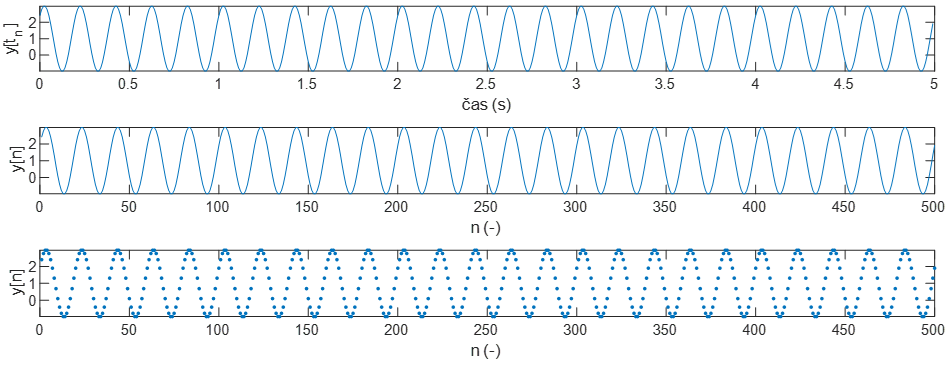

Uvědomte si, že ačkoliv budeme vykreslovat většinu signálů spojitě, vždy se bude jednat pouze o diskrétní signál jako je na subplot(3,1,3).

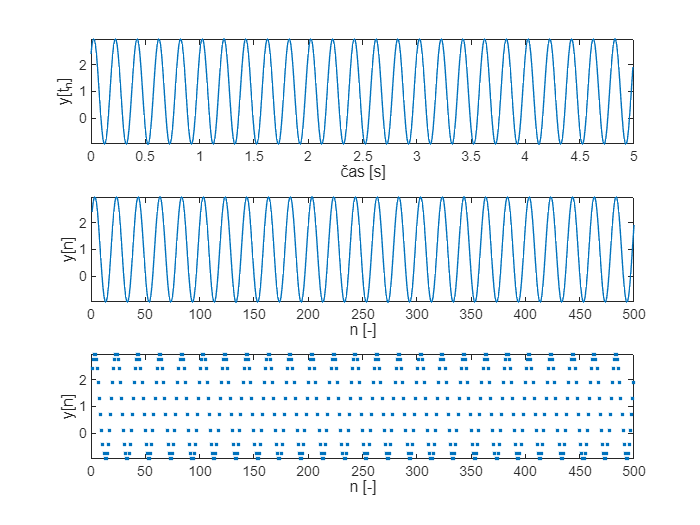

figure
subplot(3,1,1);
plot(t,y)
xlabel("čas [s]")
ylabel("y[t_n]")
n=1:(T*fs);
subplot(3,1,2);
plot(n,y)
xlabel("n [-]");
ylabel("y[n]")
subplot(3,1,3)
plot(n,y,".")
xlabel("n [-]");
ylabel("y[n]")

### **DFS**

#### **1) Výpočet spektra signálu**

Vytvořte si signál součtem dvojice harmonických signálů. Doba trvání signálů může být např. $T=2\;\mathrm{s}$ (celý násobek periody harmonických složek).

% 1. harmonická složka y1[t]
f1=5; % Hz
A1=1; % V
phi1=0; % rad

% 2. harmonická složka y2[t]
f2=15; % Hz
A2=0.5; % V
phi2=-pi/2; % rad


Generujte časovou osu `t` platnou pro vzorkovací kmitočet `fs`. **Doplňte kód:**

fs=100; % Hz
T=2; % s
N = fs*T;
n = 1:N; 
t=0:1/fs:T-1/fs;
            % časová osa od 0 po T-1/fs (s) pro T*fs vzorků

 **Generujte signál jako součet dvojice harmonických signálů a zobrazte výsledek:**


$$y\left\lbrack t_n \right\rbrack =A_1 \cdot \sin \left(2\pi f_1 t+\varphi_1 \right)+A_2 \cdot \sin \left(2\pi f_2 t+\varphi_2 \right)$$


 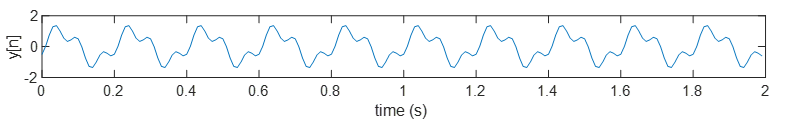

Pozn.: Nezapomeňte popsat osy, platí i pro budoucí grafy

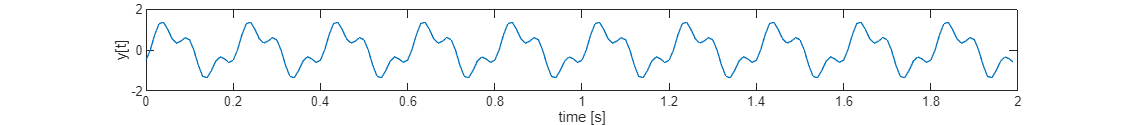

yt = A1*sin(2*pi*f1*t+phi1)+A2*sin(2*pi*f2*t+phi2);        % y[t]= y1[t]+y2[t]
figure
%subplot(2,1,1)
plot(t,yt)
set(gcf, 'Position', [0 0 900 100]);
xlabel("time [s]")
ylabel("y[t]")

**Spočtěte komplexní Fourierovo spektrum **$Y\left\lbrack k\right\rbrack$** signálu**$y\left\lbrack n\right\rbrack$ **a vygenerujte frekvenční osu **$f_k$**.**


$$Y\left\lbrack k\right\rbrack =\textrm{FFT}\left\lbrace y\left\lbrack n\right\rbrack \right\rbrace$$



$$\begin{array}{l}
\left.f_k \in <0;f_s \right)\;\\
f_k =\frac{{k\;f}_s }{N}\ldotp \ldotp \ldotp Y\left\lbrack f_k \right\rbrack \\
K=N;
\end{array}$$


Dle definice výše bude počet spektrálních čar `K` odpovídat počtu vzorků v signálu `N`. Hodnoty frekvenční osy tedy budou od stejnosměrné složky $f_k =0$(pro $k=0$) po $f_k =f_s -\frac{f_s }{N}$ (pro $k=K-1$). Pro generování frekvenční osy využijte funkce `linspace `nebo generování vektoru s krokem.


Y=(1/N)*fft(yt)% Y[k] komplexní spektrum

Y =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.5000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.2500 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i


f = linspace(0,fs-fs/N,N)

f =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000


**Pomocí funkce stem zobrazte amplitudové i fázové spektrum:**


$$\begin{array}{l}
|Y\left\lbrack f_k \right\rbrack |\\
\varphi \left\lbrack f_k \right\rbrack 
\end{array}$$


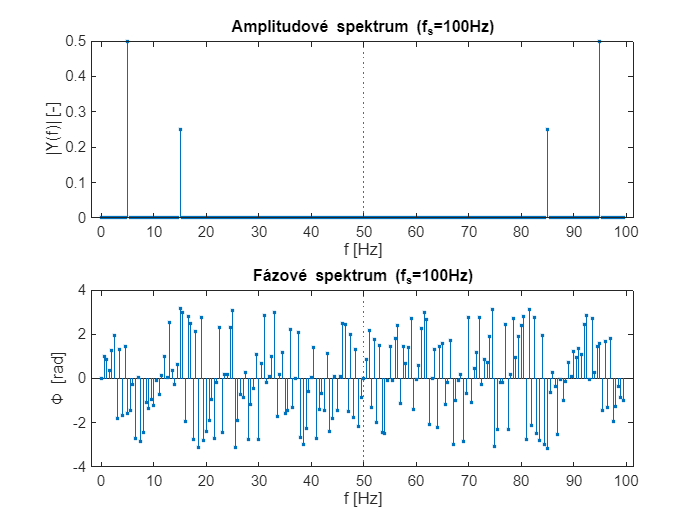

figure
subplot(2,1,1)
stem(f,abs(Y),'.')% |Y[f]| absolutní spektrum (magnitude)
xline(fs/2,":")
ylabel("|Y(f)| [-]");
xlabel("f [Hz]");
title("Amplitudové spektrum (f_s=100Hz)")

subplot(2,1,2)
stem(f,angle(Y),".")% Phi(Y[f]) fázové spektrum (phi)
xline(fs/2,":")
title("Fázové spektrum (f_s=100Hz)")
xlabel("f [Hz]")
ylabel("\Phi [rad]")

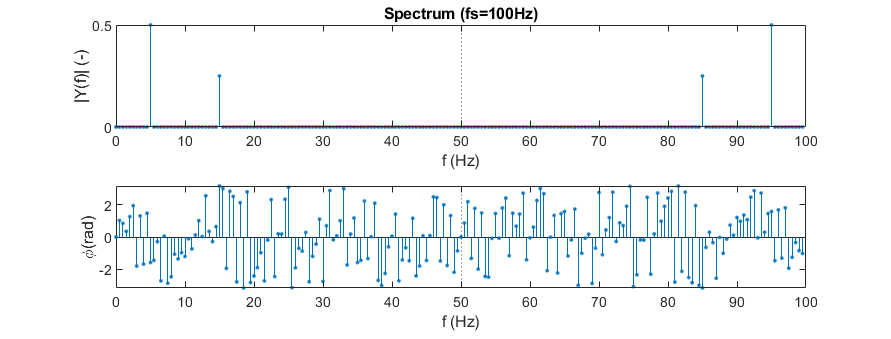

V absolutním spektru nalezněte nenulové frekvenční komponenty (kvůli kvantizačnímu šumu např. $Y\left\lbrack k\right\rbrack >10^{-6}$). 

k=find(abs(Y)>1e-6) % množina nenulových spektrálních čar 

k =     11    31   171   191


disp(f(k)) % vypíše hodnotu frekvence k-té spektrální čáry

     5    15    85    95



Z nalezených spektrálních čar vygenerujte časové průběhy:


$$y_k \left\lbrack t_n \right\rbrack =Y\left\lbrack k\right\rbrack e^{i\Omega_k n} =Y\left\lbrack k\right\rbrack e^{\textrm{i2}\pi {\;f}_k \cdot \frac{n}{f_s }} =$$

$$Y\left\lbrack k\right\rbrack e^{\textrm{i2}\pi {\;f}_k \cdot t_n }$$


**Dokončete kód:**

y1=Y(k(1))*exp(1i*2*pi*f(k(1)).*(n/fs)); %pro Y(k(1)) a f(k(1))
y2=Y(k(2))*exp(1i*2*pi*f(k(2)).*(n/fs)); %pro Y(k(2)) a f(k(2))
y3=Y(k(3))*exp(1i*2*pi*f(k(3)).*(n/fs)); %pro Y(k(3)) a f(k(3))
y4=Y(k(4))*exp(1i*2*pi*f(k(4)).*(n/fs)); %pro Y(k(4)) a f(k(4))

y1=real(y1); % pouze reálná část kvůli numerické nepřesnosti
y2=real(y2); % pouze reálná část kvůli numerické nepřesnosti
y3=real(y3); % pouze reálná část kvůli numerické nepřesnosti
y4=real(y4); % pouze reálná část kvůli numerické nepřesnosti


**Sečtěte všechny komponenty **$y^{\prime } \left\lbrack t_n \right\rbrack =y_1 \left\lbrack t_n \right\rbrack +y_2 \left\lbrack t_n \right\rbrack +y_3 \left\lbrack t_n \right\rbrack +y_4 \left\lbrack t_n \right\rbrack$**, všechny průběhy zobrazte v subplot 6 x 1 a součet porovnejte s originálním signálem **$y\left\lbrack t_n \right\rbrack \Leftrightarrow y^{\prime } \left\lbrack t_n \right\rbrack$:

 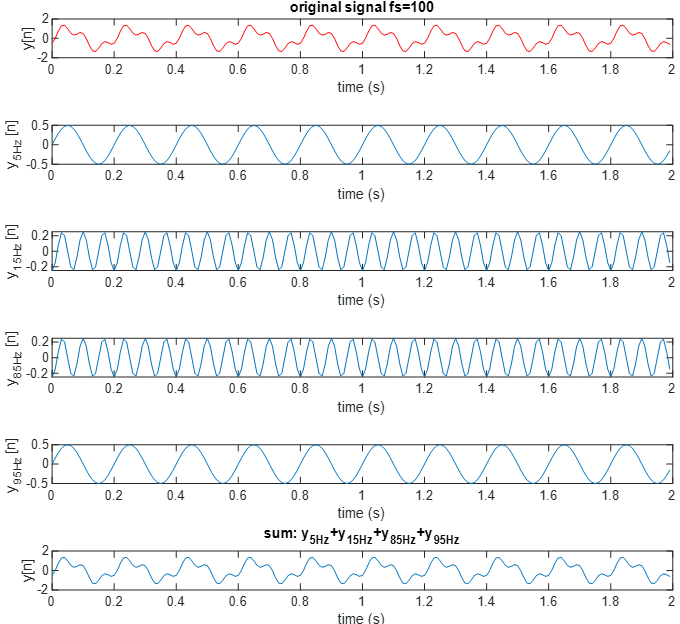

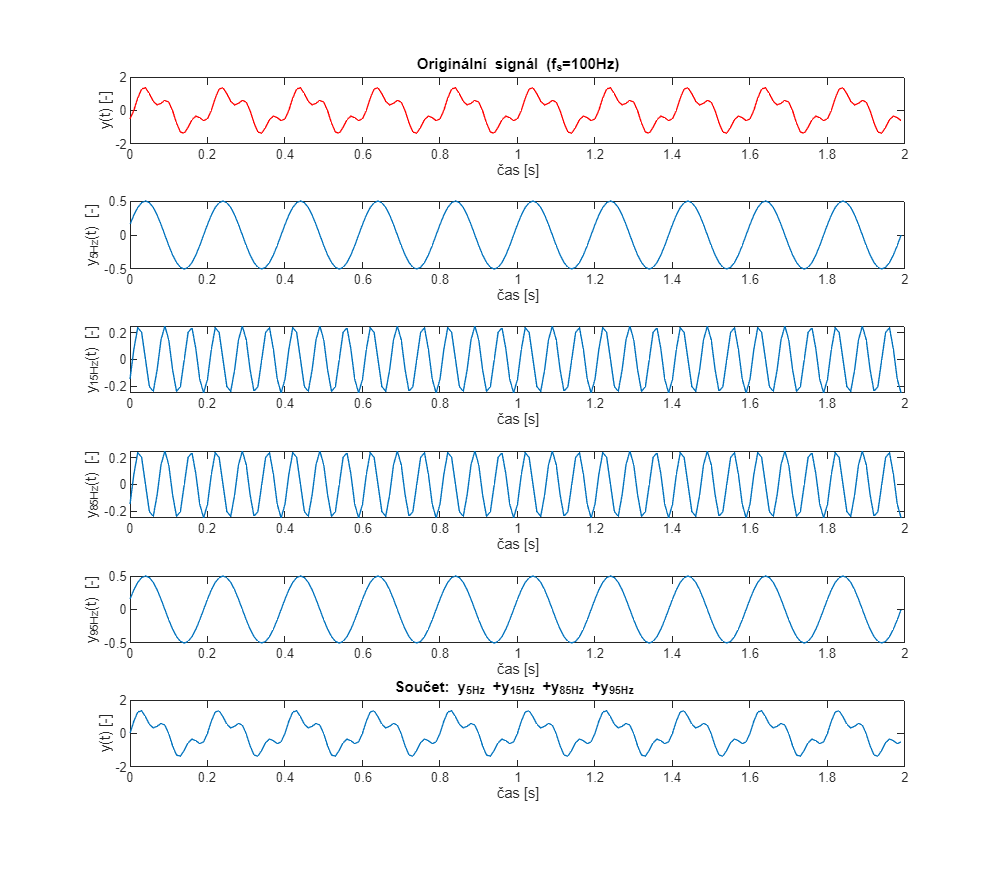

y_sum = y1 + y2 + y3 + y4;
figure
set(gcf, 'Position', [0 0 800 700]);
subplot(6,1,1);
plot(t,yt,Color="red")
title("Originální signál (f_s=100Hz)")
ylabel("y(t) [-]")
xlabel("čas [s]")

subplot(6,1,2);
plot(t,y1)
ylabel("y_{5Hz}(t) [-]")
xlabel("čas [s]")

subplot(6,1,3);
plot(t,y2)
ylabel("y_{15Hz}(t) [-]")
xlabel("čas [s]")

subplot(6,1,4);
plot(t,y3)
ylabel("y_{85Hz}(t) [-]")
xlabel("čas [s]")

subplot(6,1,5);
plot(t,y4)
ylabel("y_{95Hz}(t) [-]")
xlabel("čas [s]")

subplot(6,1,6)
plot(t,y_sum)
title("Součet: y_{5Hz} +y_{15Hz} +y_{85Hz} +y_{95Hz} ")
ylabel("y(t) [-]")
xlabel("čas [s]")

**Odpovězte na otázky:**

**1) vysvětlete, proč harmonická složka **$y_{5\textrm{Hz}} \left\lbrack t_n \right\rbrack$** vypadá jako **$y_{95\textrm{Hz}} \left\lbrack t_n \right\rbrack$**, respektive **$y_{15\textrm{Hz}} \left\lbrack t_n \right\rbrack$** jako **$y_{85\textrm{Hz}} \left\lbrack t_n \right\rbrack$**:**

Frekvenční spektrum DTF je periodické s periodou odpovídající vzorkovací frekvenci (fs =100Hz) a symetrické kolem fs/2 (50Hz). 

Při vzorkovací frekvenci 100Hz nejde rozeznat zda se jedná o harmonickou složku s frekvencí 5Hz (15Hz) nebo 95Hz (85Hz). 

**2) Jaká je perioda zobrazeného signálu **$y_{95\textrm{Hz}} \left\lbrack t_n \right\rbrack$** a tedy jeho frekvence? Jak a proč se liší frekvence zobrazená a frekvence odpovídající spektrální čáře 95 Hz?**

Perioda zobrazeného signálu y95Hz je 0.2s, což odpovídá frekvenci 5Hz. Zobrazený signál byl vzorkován frekvencí 100Hz, což porušuje Nyquistovo kritérium pro frekvenci odpovídající spektrální čáře 95Hz. Došlo tedy k aliasingu a signál se zobrazil s frekvencí 5Hz.

### **Užitečné signály a jejich spektra**

#### Jednotkový impuls

Jednotkový impuls je první pohled jednoduchý a nenápadný signál, kde první prvek je roven jedné a zbytek je nulových, nabývá ve spektru konstanty (tzn. má všechny kmitočty). Můžeme samozřejmě signál časově zpozdit a tedy jednička nebude na první pozici, ale stále platí, že všechny ostatní vzorky jsou nulové. Jednotkový impuls budeme využívat pro popis digitálních systémů v následujících cvičení. Také se používá v syntéze periodických signálů (např. u řeči na znělé hlásky).

Pozn.: Pro popis analogových systémů by se použil Dirakův impuls, který v čase 0 má nekonečnou amplitudu a ve zbytku času je nulový. Spektrálně potom také odpovídá konstantě.

**Vygenerujte jednotkový impuls pro *****N***** = 500 a **$f_s =500$** Hz, jeho NEnormované amplitudové spektrum, fázové spektrum a zobrazte do jednoho obrázku**

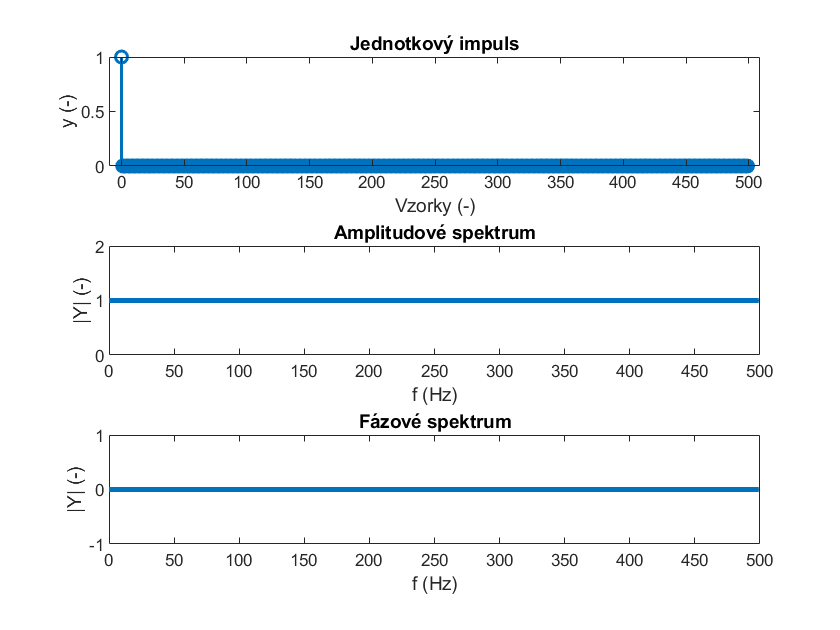

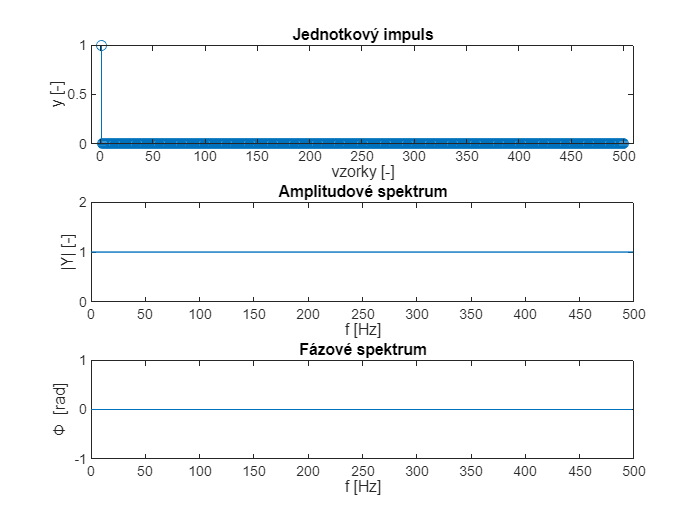

N = 500; % počet vzorků
fs = 500; % Hz, vzorkovací frekvence
t = 1:N;
jednotkovy_impuls = [1 zeros(N-1,1)'];

Y = fft(jednotkovy_impuls);
f = linspace(0,fs-fs/N,N);
figure
subplot(3,1,1)
stem(t, jednotkovy_impuls)
title("Jednotkový impuls")
ylabel("y [-]")
xlabel("vzorky [-]")

subplot(3,1,2)
plot(f,abs(Y))
title("Amplitudové spektrum")
ylabel("|Y| [-]")
xlabel("f [Hz]")

subplot(3,1,3)
plot(f, angle(Y))
title("Fázové spektrum")
ylabel("\Phi [rad]")
xlabel("f [Hz]")

#### Šum s normálním rozdělením

Šum s normálním rozdělením (nebo také šum s Gaussovským rozdělením, nebo bílý šum) je nejrozšířenější šum. Spektrálně, podobně jako jednotkový impuls, obsahuje všechny frekvence, a proto se také široce využívá (např. muzice jako podklad, u syntézy řeči na neznělé hlásky, testování systému na odolnost proti šumu, atp.). 

**Vygenerujte bílý šum:**

- **o *****N *****= 100 vzorků a **$f_s =100$** Hz,**

- **o *****N***** = 100 000 vzorků a **$f_s =100$** Hz.**

**Vykreslete signály a normované amplitudové spektrum.**

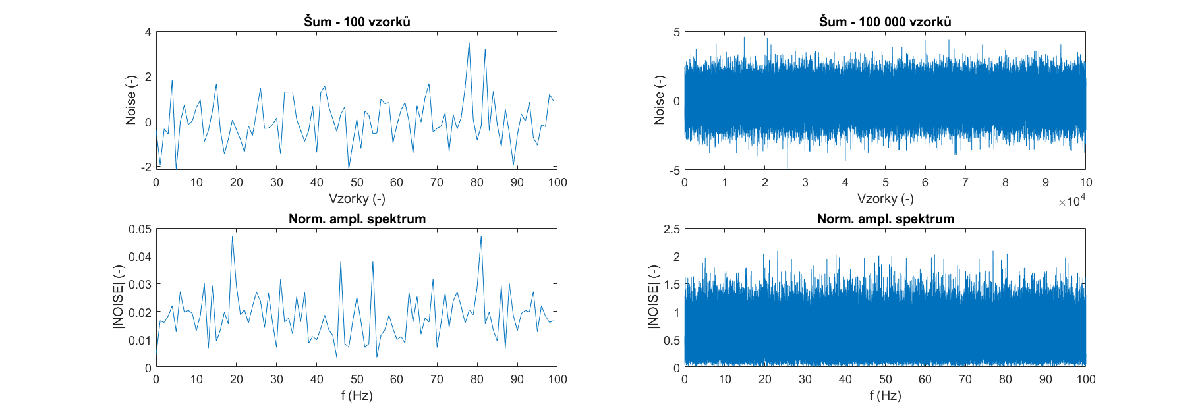

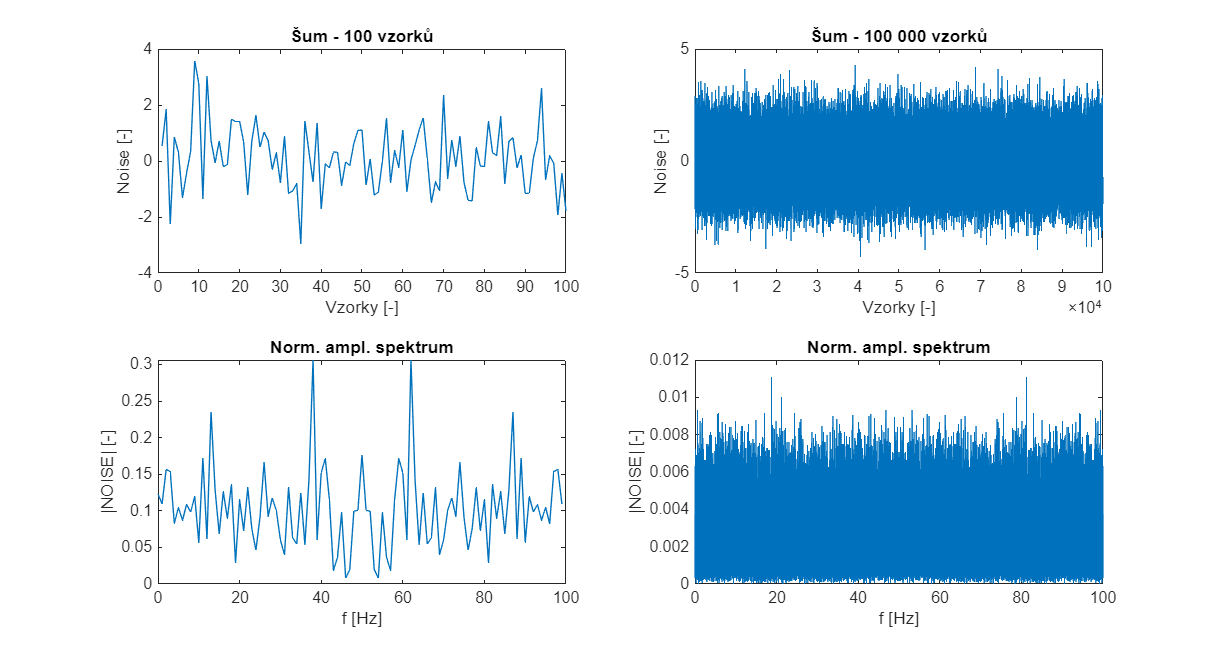

N = 100;
noise = randn(N,1);
N2 = 100000;
NOISE = randn(N2,1);
fs = 100;

Y1 = (1/N)*fft(noise);
Y2 = (1/N2)*fft(NOISE);

f = linspace(0,fs-fs/N,N);
f2 = linspace(0,fs-fs/N2,N2);
figure
set(gcf, 'Position', [0 0 1300 700]);
subplot(2,2,1);
plot(1:N,noise)
xticks(0:N/10:N)
title("Šum - 100 vzorků")
ylabel("Noise [-]")
xlabel("Vzorky [-]")

subplot(2,2,2)
plot(1:N2, NOISE)
xticks(0:N2/10:N2)
title("Šum - 100 000 vzorků")
ylabel("Noise [-]")
xlabel("Vzorky [-]")

subplot(2,2,3)
plot(f,abs(Y1))
title("Norm. ampl. spektrum")
ylabel("|NOISE| [-]")
xlabel("f [Hz]")

subplot(2,2,4)
plot(f2,abs(Y2))
title("Norm. ampl. spektrum")
ylabel("|NOISE| [-]")
xlabel("f [Hz]")

## Bonus (1b)

Obdélníkový signál je velmi jednoduchý technický signál, jež je v digitální a měřicí technice hojně využíván.

### Obdélníkový signál

Obdélníkový signál můžeme vytvořit několika způsoby. Např. maticově spojením jedničkového a nuluvého vektoru (`zeros`, `ones`), pomocí funkcí sinus a signum (s dodatkem pro nulu), ale můžeme využít i funkce z Signal processing toolboxu - `square`.

**Vytvořte obdélníkové průběhy s základním kmitočtem **$f_0 =2$**Hz, délkou signálu **$T=3$**s a vzorkovacím kmitočtem **$f_s =50$**Hz:**

- **bez posunu fáze, s minimem -1 V a maximem +1 V a střídou 0,5** (tzn. nulová stejnosměrná složka, střída je poměr časů obdélníka v hodnotě maxima a periody),

- **bez posunu fáze, s minimem 0 V a maximem +2 V a střídou 0,5 **(tzn. stejnosměrná složka rovna jedné),

- **s posunem fáze o **$\frac{\pi }{2}$**, s minimem -1 V a maximem +1 V a střídou 0,5.**

Pozn.: Zbylé dva signály snadno vytvoříte z prvního signálu. Buď přičtením konstanty nebo pomocí indexace.

f = 2;
fs = 50;
T = 3;
N = T/(1/fs)

N = 150

t = 0:1/fs:T-1/fs;
signal1 = square(2*pi*f.*t);
signal2 = 1+signal1;
signal3 = square(2*pi*f.*t + pi/2);
y1 = (1/N).*fft(signal1);
y2 = (1/N).*fft(signal2);
y3 = (1/N).*fft(signal3);

T = 1/f;
idx = t<T ;
one_period1 = signal1(idx);
one_period2 = signal2(idx);
one_period3 = signal3(idx);
t_one_period= t(idx);



**Do jednoho obrázku pod sebe vykreslete první periody signálů a amplitudové spektra** (z celých signálů, mohou být nenormovaná).

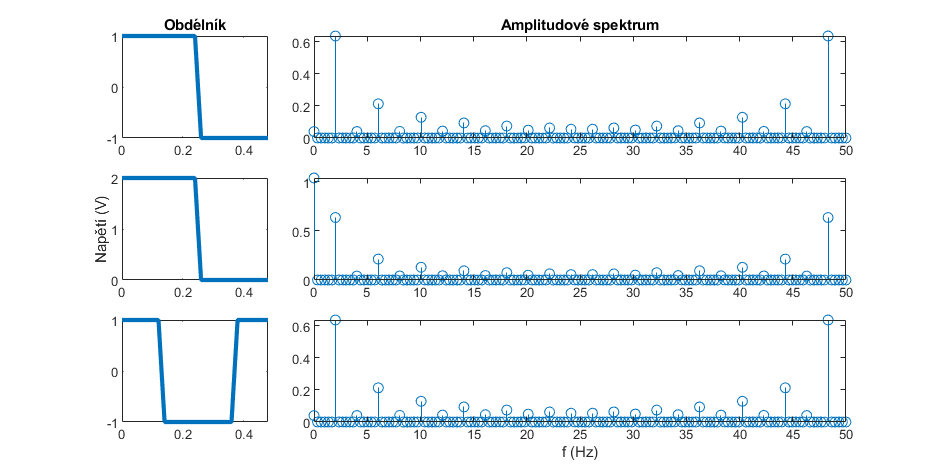

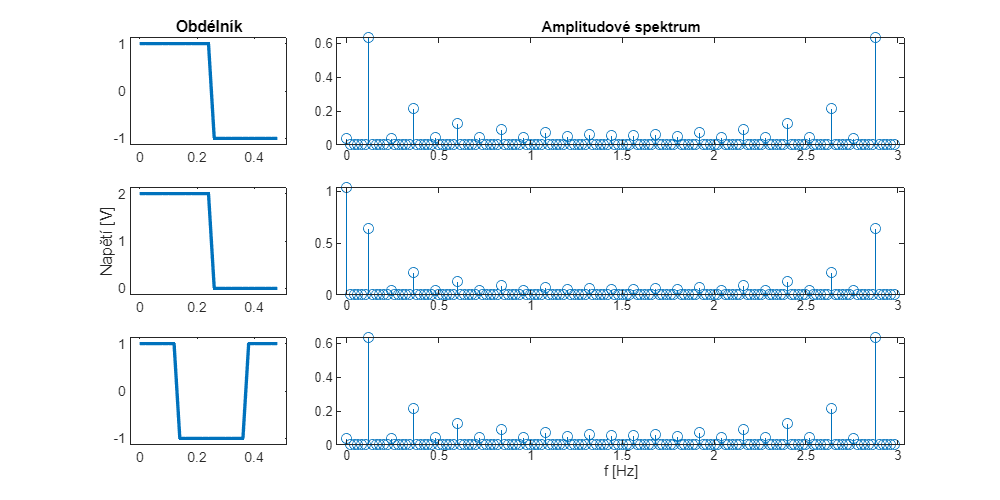

figure
set(gcf, 'Position', [0 0 800 400]);
subplot(3,4,1)
plot(t_one_period, one_period1,LineWidth=2)
axis padded
title("Obdélník")

subplot(3,4,[2 3 4])
stem(t,abs(y1))
title("Amplitudové spektrum")

subplot(3,4,5)
plot(t_one_period, one_period2,LineWidth=2)
axis padded
ylabel("Napětí [V]")

subplot(3,4, [6 7 8])
stem(t,abs(y2))

subplot(3,4,9)
plot(t_one_period, one_period3,LineWidth=2)
axis padded

subplot(3,4, [10 11 12])
stem(t,abs(y3))
xlabel("f [Hz]")

**Stejně pro fázové spektrum**

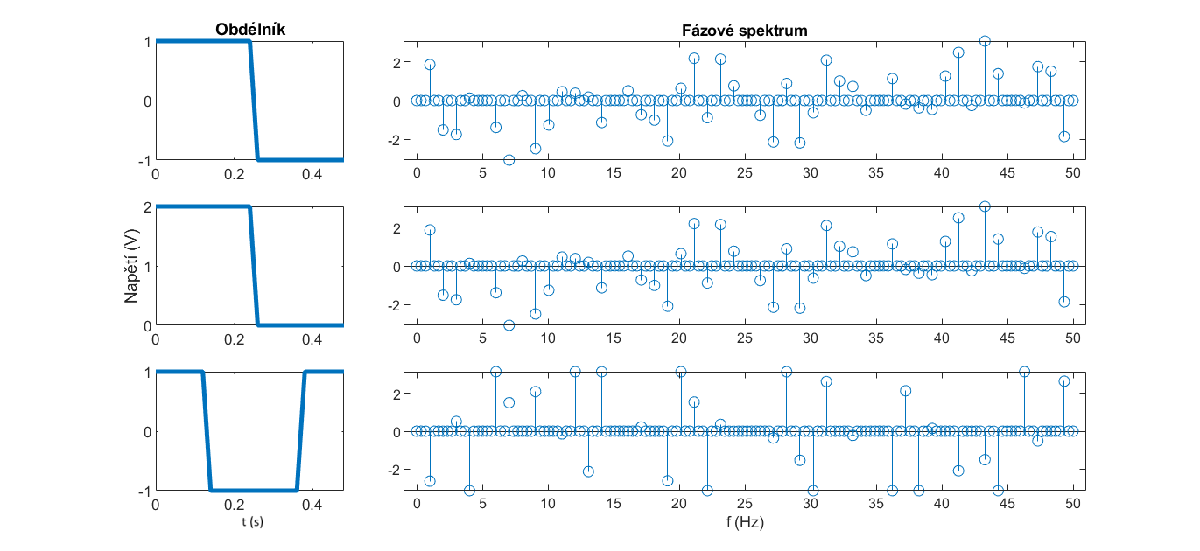

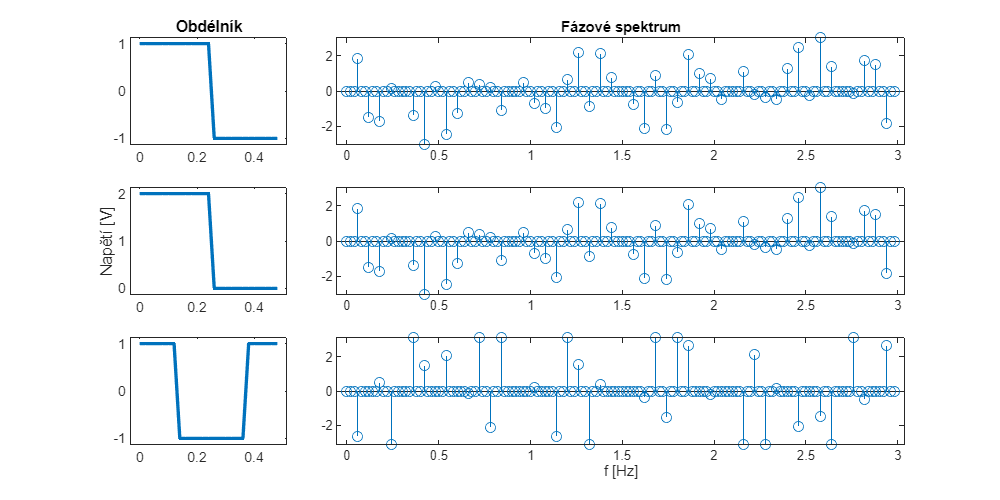

figure
set(gcf, 'Position', [0 0 800 400]);
subplot(3,4,1)
plot(t_one_period, one_period1,LineWidth=2)
axis padded
title("Obdélník")

subplot(3,4,[2 3 4])
stem(t,angle(y1))
title("Fázové spektrum")

subplot(3,4,5)
plot(t_one_period, one_period2,LineWidth=2)
axis padded
ylabel("Napětí [V]")

subplot(3,4, [6 7 8])
stem(t,angle(y2))

subplot(3,4,9)
plot(t_one_period, one_period3,LineWidth=2)
axis padded

subplot(3,4, [10 11 12])
stem(t,angle(y3))
xlabel("f [Hz]")

**Pozn.: **Ačkoli se jedná o stejný průběh pouze s rozdílem v amplitudě nebo v fázi, i patřičná spektra se budou lišit. Např.pro první dva signály je rozdíl ve stejnosměrné složce, což se projeví rozdílným magnitudovým spektrem, ale stejným fázovým. Obráceně, magnituvové spektrum prvního a třetího je stejné, liší se však fázové.